figure

load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
I = I./1000;
P = P./1000;
plot(I, P, 'oc')
hold on

load TiCMOS.mat
lambda = 0.327974911948322;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
T = Ti(:, 2:end);
It = repmat(Ti(:, 1), 9);
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Pi = lambda.*(It(1:251, :) - Ith0 - Ioff);
Pi(Pi<0) = 0;
H1 = plot(Ti(:,1), Pi, '.r')

H1 =   9×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


hold on

load Ti.mat
lambda = 0.327974911948322;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
T = Ti(:, 2:end);
It = repmat(Ti(:, 1), 9);
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Pi = lambda.*(It(1:251, :) - Ith0 - Ioff);
Pi(Pi<0) = 0;
H2 = plot(Ti(:,1), Pi, '--k')

H2 =   9×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


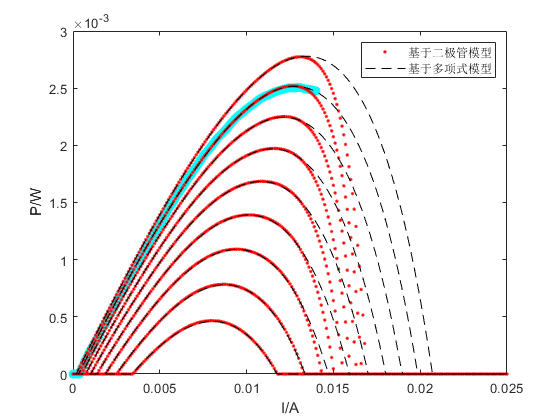

% legend(H1, '基于二极管模型')
% legend(H2, '基于多项式模型')
legend([H1(1), H2(1)], '基于二极管模型', '基于多项式模型')
xlabel('I/A')
ylabel('P/W')
saveas(gcf, 'fig13.png');

load 3.mat
load TiCMOS.mat
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
f = 0:1e7:4e10;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;
% x = target;
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2./Ps;

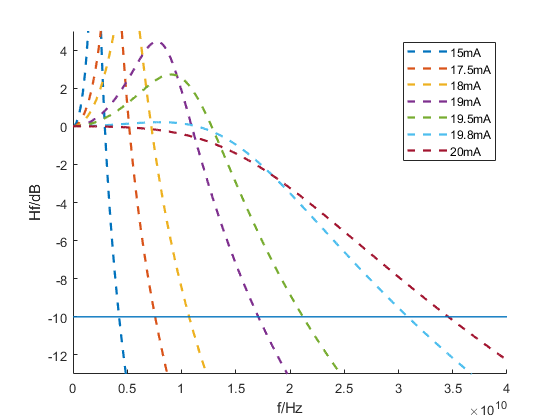

load 3.mat
load TiCMOS.mat
% load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
f = 0:1e7:4e10;
Ia = [0.5 0.7 1 2 3 7.5 14].*1e-3;

% I = 0:1e-4:0.04;

T = 273.15 + 20;
Rs = 57.8774072057481;
Vt = 0.150069586007959;
Is = 9.69996336936704e-09;
I = Ti(:, 1);
U = I.*Rs + Vt.*log(1 + I./Is);
lambda = 0.327974911948322;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
P = lambda.*(I - Ith0 - Ioff);
P(P<0) = 0;
temp1 = [];

figure
for i = 1:length(Ia)
    I_temp = Ia(i);
    U_temp = U(abs((I-Ia(i)))<1e-10);
    P_temp = P(abs((I-Ia(i)))<1e-10);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = 293.15 + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(f, M, '--', 'linewidth',1.7)
    [a, b] = min(abs(M+10));
    temp1(i, 1) = Ia(i);
    temp1(i, 2) = f(b);
end



y_1=[0, 4E10];
y_2=[-10, -10];
plot(y_1,y_2, 'linewidth',1)
axis([0 4E10 -13 5])
legend('15mA', '17.5mA', '18mA', '19mA', '19.5mA', '19.8mA', '20mA')
xlabel('f/Hz')
ylabel('Hf/dB')

% saveas(gcf, 'fig16_2.png');
temp1

temp1 = 	1.0e+10 *

    0.0000    0.4250
    0.0000    0.7570
    0.0000    1.0700
    0.0000    1.7080
    0.0000    2.1200
    0.0000    3.0850
    0.0000    3.4590


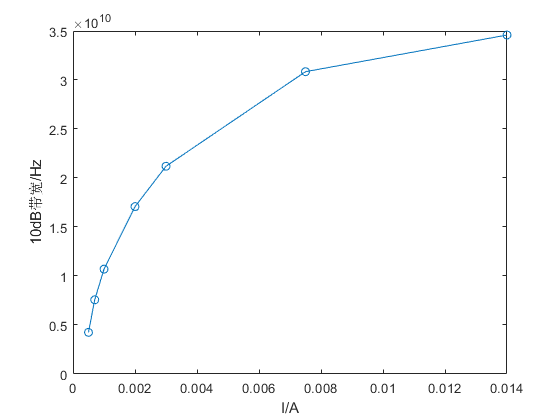

figure
plot(temp1(:, 1), temp1(:, 2), 'o-')
xlabel('I/A')
ylabel('10dB带宽/Hz')
saveas(gcf, 'fig17.png');

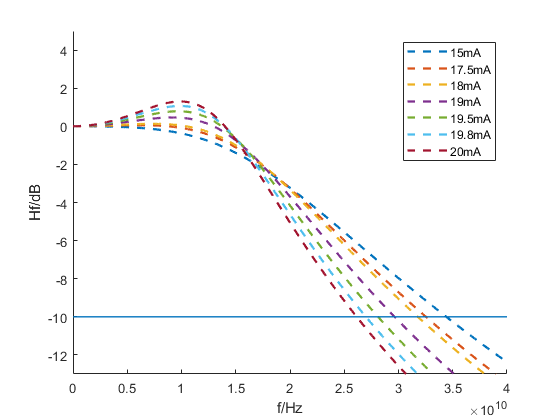

load 3.mat
load TiCMOS.mat
% load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
f = 0:1e7:4e10;
Ia = [15 17.5 18 19 19.5 19.8 20].*1e-3;

% I = 0:1e-4:0.04;

T = 273.15 + 20;
Rs = 57.8774072057481;
Vt = 0.150069586007959;
Is = 9.69996336936704e-09;
I = Ti(:, 1);
U = I.*Rs + Vt.*log(1 + I./Is);
lambda = 0.327974911948322;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
P = lambda.*(I - Ith0 - Ioff);
P(P<0) = 0;
temp = [];

figure
for i = 1:length(Ia)
    I_temp = Ia(i);
    U_temp = U(abs((I-Ia(i)))<1e-10);
    P_temp = P(abs((I-Ia(i)))<1e-10);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = 293.15 + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(f, M, '--', 'linewidth',1.7)
    [a, b] = min(abs(M+10));
    temp(i, 1) = Ia(i);
    temp(i, 2) = f(b);
end



y_1=[0, 4E10];
y_2=[-10, -10];
plot(y_1,y_2, 'linewidth',1)
axis([0 4E10 -13 5])
legend('15mA', '17.5mA', '18mA', '19mA', '19.5mA', '19.8mA', '20mA')
xlabel('f/Hz')
ylabel('Hf/dB')
saveas(gcf, 'fig16_2.png');

temp

temp = 	1.0e+10 *

    0.0000    3.4410
    0.0000    3.2530
    0.0000    3.1780
    0.0000    2.9640
    0.0000    2.8120
    0.0000    2.7000
    0.0000    2.6150


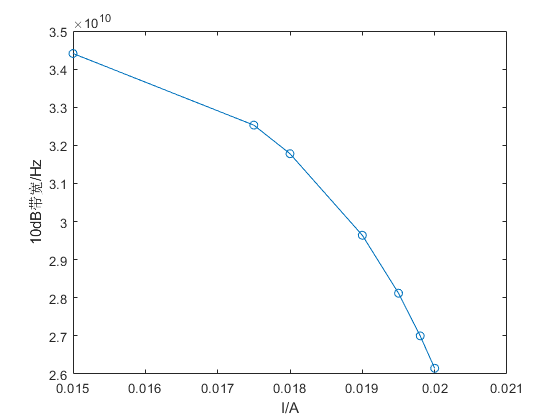

figure
plot(temp(:, 1), temp(:, 2), 'o-')
xlabel('I/A')
ylabel('10dB带宽/Hz')
saveas(gcf, 'fig17.png');

tt = [temp1;temp]

tt = 	1.0e+10 *

    0.0000    0.4250
    0.0000    0.7570
    0.0000    1.0700
    0.0000    1.7080
    0.0000    2.1200
    0.0000    3.0850
    0.0000    3.4590
    0.0000    3.4410
    0.0000    3.2530
    0.0000    3.1780


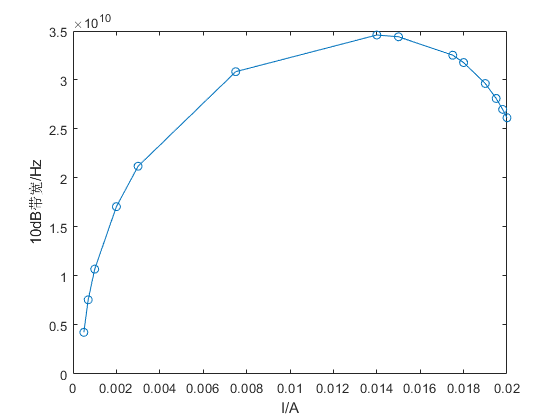

figure
plot(tt(:, 1), tt(:, 2), 'o-')
xlabel('I/A')
ylabel('10dB带宽/Hz')
saveas(gcf, 'fig17.png');

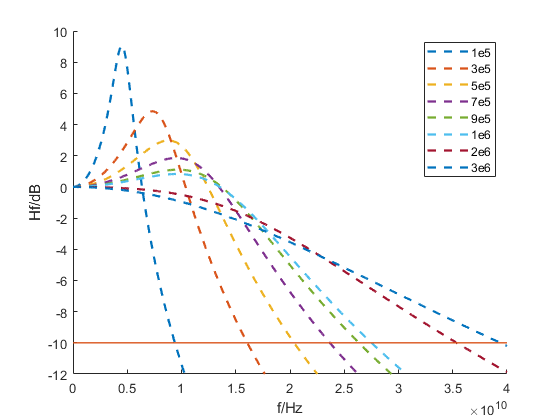

load 3.mat
load TiCMOS.mat
% load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
f = 0:1e7:4e10;
Ia = [7.5].*1e-3;

% I = 0:1e-4:0.04;

T = 273.15 + 20;
Rs = 57.8774072057481;
Vt = 0.150069586007959;
Is = 9.69996336936704e-09;
I = Ti(:, 1);
U = I.*Rs + Vt.*log(1 + I./Is);
lambda = 0.327974911948322;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
P = lambda.*(I - Ith0 - Ioff);
P(P<0) = 0;
G0 = [1e5 3e5 5e5 7e5 9e5 1e6 2e6 3e6];
temp = [];
figure
for i = 1:length(G0)
    I_temp = Ia;
    U_temp = U(abs((I-Ia))<1e-10);
    P_temp = P(abs((I-Ia))<1e-10);
    x(5) = G0(i);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = 293.15 + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(f, M, '--', 'linewidth',1.7)
    [a, b] = min(abs(M+10));
    temp(i, 1) = G0(i);
    temp(i, 2) = f(b);
end



y_1=[0, 4E10];
y_2=[-10, -10];
plot(y_1,y_2, 'linewidth',1)
axis([0 4E10 -12 10])
legend('1e5', '3e5', '5e5', '7e5', '9e5', '1e6', '2e6', '3e6');
xlabel('f/Hz')
ylabel('Hf/dB')
saveas(gcf, 'fig22.png');

temp

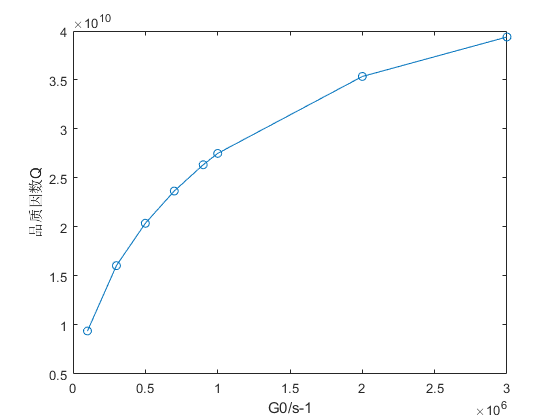

figure
plot(temp(:, 1), temp(:, 2), 'o-')
xlabel('G0/s-1')
% ylabel('10dB带宽/Hz')
ylabel('品质因数Q')
saveas(gcf, 'fig23.png');

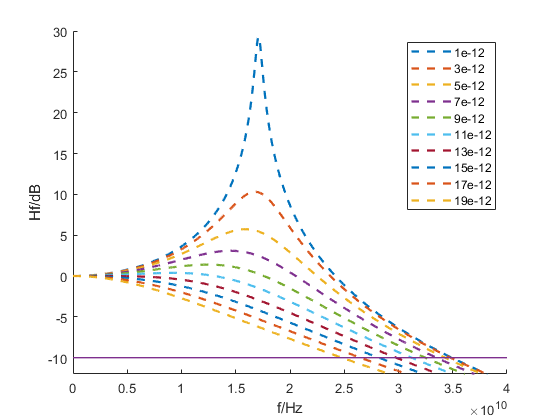

load 3.mat
load TiCMOS.mat
% load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
f = 0:1e7:4e10;
Ia = [7.5].*1e-3;

% I = 0:1e-4:0.04;

T = 273.15 + 20;
Rs = 57.8774072057481;
Vt = 0.150069586007959;
Is = 9.69996336936704e-09;
I = Ti(:, 1);
U = I.*Rs + Vt.*log(1 + I./Is);
lambda = 0.327974911948322;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
P = lambda.*(I - Ith0 - Ioff);
P(P<0) = 0;
tp = [1 3 5 7 9 11 13 15 17 19].*1e-12;
temp = [];
figure
for i = 1:length(tp)
    I_temp = Ia;
    U_temp = U(abs((I-Ia))<1e-10);
    P_temp = P(abs((I-Ia))<1e-10);
    x(7) = tp(i);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = 293.15 + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(f, M, '--', 'linewidth',1.7)
    [a, b] = min(abs(M+10));
    temp(i, 1) = tp(i);
    temp(i, 2) = f(b);
end



y_1=[0, 4E10];
y_2=[-10, -10];
plot(y_1,y_2, 'linewidth',1)
axis([0 4E10 -12 30])
legend('1e-12', '3e-12', '5e-12', '7e-12', '9e-12', '11e-12', '13e-12', '15e-12', '17e-12', '19e-12');
xlabel('f/Hz')
ylabel('Hf/dB')
saveas(gcf, 'fig24.png');

temp

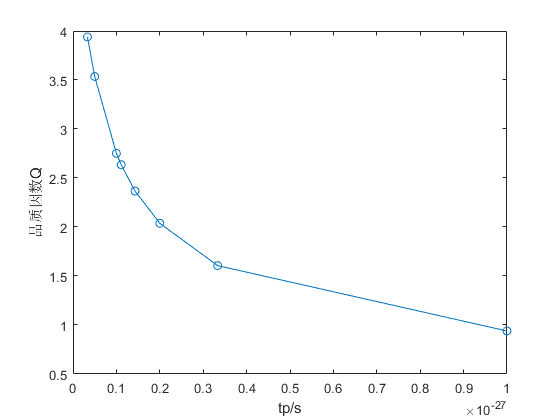

figure
plot(1e-22./temp(:, 1), temp(:, 2).*1e-10, 'o-')
xlabel('tp/s')
% ylabel('10dB带宽/Hz')
ylabel('品质因数Q')
saveas(gcf, 'fig25.png');

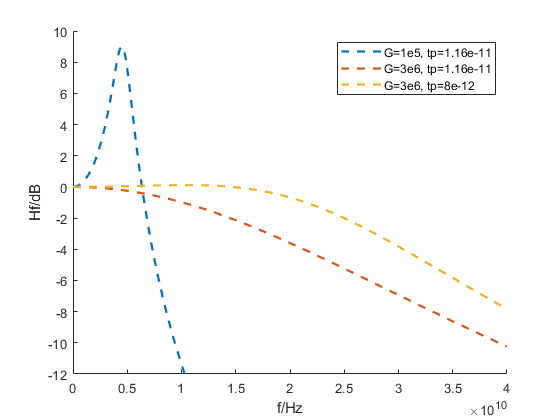

load 3.mat
load TiCMOS.mat
% load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
figure
f = 0:1e7:4e10;
Ia = [7.5].*1e-3;

% I = 0:1e-4:0.04;

T = 273.15 + 20;
Rs = 57.8774072057481;
Vt = 0.150069586007959;
Is = 9.69996336936704e-09;
I = Ti(:, 1);
U = I.*Rs + Vt.*log(1 + I./Is);
lambda = 0.327974911948322;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
P = lambda.*(I - Ith0 - Ioff);
P(P<0) = 0;


I_temp = Ia;
U_temp = U(abs((I-Ia))<1e-10);
P_temp = P(abs((I-Ia))<1e-10);
x(5) = 1e5;
x(7) = 1.16e-11;
Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
T1 = 293.15 + (I_temp.*U_temp - P_temp).*Rth;
Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
Ps1 = x(4).*Ss1;
Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
M=20*log10(abs(H));
hold on
plot(f, M, '--', 'linewidth',1.7)
% [a, b] = min(abs(M+10));
% temp(i, 1) = tp(i);
% temp(i, 2) = f(b);

x(5) = 3e6;
x(7) = 1.16e-11;
Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
T1 = 293.15 + (I_temp.*U_temp - P_temp).*Rth;
Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
Ps1 = x(4).*Ss1;
Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
M=20*log10(abs(H));
hold on
plot(f, M, '--', 'linewidth',1.7)


x(5) = 3e6;
x(7) = 8e-12;
Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
T1 = 293.15 + (I_temp.*U_temp - P_temp).*Rth;
Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
Ps1 = x(4).*Ss1;
Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
M=20*log10(abs(H));
hold on
plot(f, M, '--', 'linewidth',1.7)

legend('G=1e5, tp=1.16e-11', 'G=3e6, tp=1.16e-11', 'G=3e6, tp=8e-12')



% y_1=[0, 4E10];
% y_2=[-10, -10];
% plot(y_1,y_2, 'linewidth',1)
axis([0 4E10 -12 10])
% legend('1e-12', '3e-12', '5e-12', '7e-12', '9e-12', '11e-12', '13e-12', '15e-12', '17e-12', '19e-12');
xlabel('f/Hz')
ylabel('Hf/dB')
saveas(gcf, 'fig26.png');

load 3.mat
load TiCMOS.mat
% load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
f = 0:1e7:4e10;
Ia = [15 17.5 18 19 19.5 19.8 20].*1e-3;
Ta = [10, 20, 30, 40, 50, 60, 70, 80, 90] + 273.15;
[Tx Ty] = meshgrid(Ia, Ta)

Tx =     0.0150    0.0175    0.0180    0.0190    0.0195    0.0198    0.0200
    0.0150    0.0175    0.0180    0.0190    0.0195    0.0198    0.0200
    0.0150    0.0175    0.0180    0.0190    0.0195    0.0198    0.0200
    0.0150    0.0175    0.0180    0.0190    0.0195    0.0198    0.0200
    0.0150    0.0175    0.0180    0.0190    0.0195    0.0198    0.0200
    0.0150    0.0175    0.0180    0.0190    0.0195    0.0198    0.0200
    0.0150    0.0175    0.0180    0.0190    0.0195    0.0198    0.0200
    0.0150    0.0175    0.0180    0.0190    0.0195    0.0198    0.0200
    0.0150    0.0175    0.0180    0.0190    0.0195    0.0198    0.0200


Ty =   283.1500  283.1500  283.1500  283.1500  283.1500  283.1500  283.1500
  293.1500  293.1500  293.1500  293.1500  293.1500  293.1500  293.1500
  303.1500  303.1500  303.1500  303.1500  303.1500  303.1500  303.1500
  313.1500  313.1500  313.1500  313.1500  313.1500  313.1500  313.1500
  323.1500  323.1500  323.1500  323.1500  323.1500  323.1500  323.1500
  333.1500  333.1500  333.1500  333.1500  333.1500  333.1500  333.1500
  343.1500  343.1500  343.1500  343.1500  343.1500  343.1500  343.1500
  353.1500  353.1500  353.1500  353.1500  353.1500  353.1500  353.1500
  363.1500  363.1500  363.1500  363.1500  363.1500  363.1500  363.1500


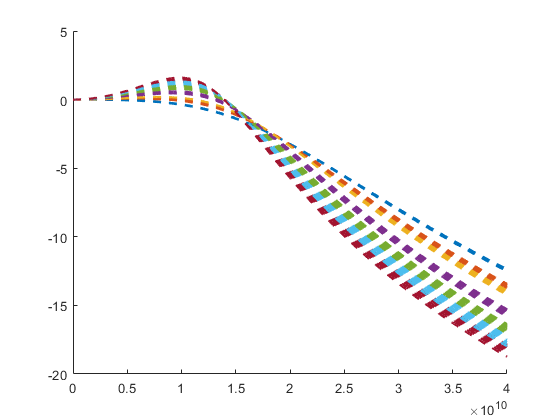

figure
temp = [];
for m = 1:length(Ta)
    for n = 1:length(Ia)
        [Tx(m, n), Ty(m, n)];
        T = Ty(m, n);
        Rs = 57.8774072057481;
        Vt = 0.150069586007959;
        Is = 9.69996336936704e-09;
        I = Ti(:, 1);
        U = I.*Rs + Vt.*log(1 + I./Is);
        lambda = 0.327974911948322;
        a_0 = 0.00245295354589810;
        a_1 = -2.24461489568760E-05;
        a_2 = 8.55495131262933E-08;
        a_3 = -3.04196846538548E-10;
        a_4 = 6.38679397411974E-13;
        Ith0 = 2.09792442194657E-05;
        Rth = 3593.49598351965;
        Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
        P = lambda.*(I - Ith0 - Ioff);
        P(P<0) = 0;

        
        I_temp = Tx(m, n);
        U_temp = U(abs((I-Tx(m, n)))<1e-10);
        P_temp = P(abs((I-Tx(m, n)))<1e-10);
        Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
        T1 = 293.15 + (I_temp.*U_temp - P_temp).*Rth;
        Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
        Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
        Ps1 = x(4).*Ss1;
        Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
        Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
        H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
        M=20*log10(abs(H));
        hold on
        plot(f, M, '--', 'linewidth',1.7)
        [a, b] = min(abs(M+10));
        temp(7*(m-1)+n, 1) = Tx(m, n);
        temp(7*(m-1)+n, 2) = Ty(m, n);
        temp(7*(m-1)+n, 3) =  f(b);

        
        
        
%         y_1=[0, 4E10];
%         y_2=[-10, -10];
%         plot(y_1,y_2, 'linewidth',1)
%         axis([0 4E10 -13 5])
%         legend('15mA', '17.5mA', '18mA', '19mA', '19.5mA', '19.8mA', '20mA')
%         xlabel('f/Hz')
%         ylabel('Hf/dB')
%         saveas(gcf, 'fig16_2.png');
%         temp
    end
end

temp

temp = 	1.0e+10 *

    0.0000    0.0000    3.4420
    0.0000    0.0000    3.2550
    0.0000    0.0000    3.1810
    0.0000    0.0000    2.9690
    0.0000    0.0000    2.8170
    0.0000    0.0000    2.7060
    0.0000    0.0000    2.6210
    0.0000    0.0000    3.4410
    0.0000    0.0000    3.2530
    0.0000    0.0000    3.1780


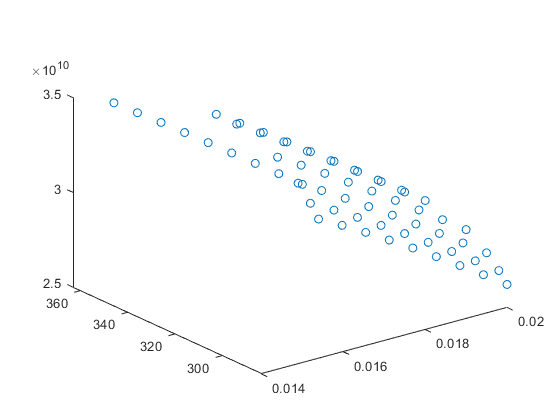

% [A B C] =
figure
plot3(temp(:,1), temp(:,2), temp(:,3), 'o');


% mesh(A,B,C)


% I = 0:1e-4:0.04;

T = 273.15 + 20;
Rs = 57.8774072057481;
Vt = 0.150069586007959;
Is = 9.69996336936704e-09;
I = Ti(:, 1);
U = I.*Rs + Vt.*log(1 + I./Is);
lambda = 0.327974911948322;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
P = lambda.*(I - Ith0 - Ioff);
P(P<0) = 0;
temp = [];

figure
for i = 1:length(Ia)
    I_temp = Ia(i);
    U_temp = U(abs((I-Ia(i)))<1e-10);
    P_temp = P(abs((I-Ia(i)))<1e-10);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = 293.15 + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(f, M, '--', 'linewidth',1.7)
    [a, b] = min(abs(M+10));
    temp(i, 1) = Ia(i);
    temp(i, 2) = f(b);
end



y_1=[0, 4E10];
y_2=[-10, -10];
plot(y_1,y_2, 'linewidth',1)
axis([0 4E10 -13 5])
legend('15mA', '17.5mA', '18mA', '19mA', '19.5mA', '19.8mA', '20mA')
xlabel('f/Hz')
ylabel('Hf/dB')
saveas(gcf, 'fig16_2.png');
temp

init = [-387040767136795 -76653.3976429894 -2042162385.28235 12542811643268.9 78031137.2567357 -74047062995.9802];

x = fminsearch(@fitness_8, init)

 
正在退出: 超过了函数计算的最大数目
 - 请增大 MaxFunEvals 选项。
 当前函数值: 1310668665314612992.000000 



x = 	1.0e+14 *

   -3.8704   -0.0000   -0.0000    0.1254    0.0000   -0.0007


% init = x;
x = init;

    load('D:\FOLDER\桌面\校数模\2017B\mesh.mat');
    T = temp(:, 2);
    I = temp(:, 1);
    BW = temp(:, 3);
    BW1 = x(1).*I.^2 + x(2).*T.^2 + x(3).*I.*T + x(4).*I + x(5).*T + x(6);
    [BW BW1]

ans = 	1.0e+10 *

    3.4420    3.4286
    3.2550    3.2751
    3.1810    3.1863
    2.9690    2.9507
    2.8170    2.8039
    2.7060    2.7065
    2.6210    2.6377
    3.4410    3.4319
    3.2530    3.2732
    3.1780    3.1834


    figure
    plot3(I, T, BW, 'o')